**Determine THD for a Signal with Two Harmonics**

The following example shows explicitly how to calculate the total harmonic distortion in dBc for a signal consisting of the fundamental and two harmonics. The explicit calculation is checked against the result returned by `thd`. Notice the additional 10*log() applied when calculating the value manually.

Create a signal sampled at 1 kHz. The signal consists of a 100 Hz fundamental with amplitude 2 and three harmonics at 200, 300, and 400 Hz with amplitudes 0.01, 0.005, and 0.0025. Obtain the total harmonic distortion explicitly and using `thd`.

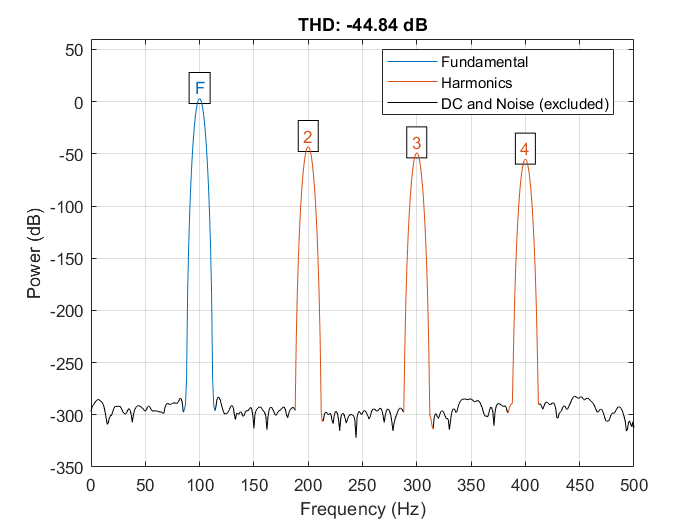

% % % clear; close all; clc;

t = 0:0.001:1-0.001;
fs = 1000;
Fn = 100;
oh = 4; % order of harmonics used in thd calcuations

x = 2*cos(2*pi*100*t)+0.01*cos(2*pi*200*t)+ ...
    0.005*cos(2*pi*300*t)+0.0025*sin(2*pi*400*t);
% % % x = 2*cos(2*pi*100*t);
fundFreq = 100;


thd(x,fs,oh);


% THD is in dB, harmPow is also in dB
[THD_MATLAB, harmPow_MATLAB, harmFreq_MATLAB] = thd(x,fs,oh);

% [pwr_V3, freq_V3] = pspectrum(x, fs);
% semilogx(freq_V3, db(pwr_V3, 'power'))


% Using fft 
[THD_THDFFT, Percent_THDFFT, amplitudes_THDFFT, powerdB_THDFFT, harmfreq_THDFFT] = THDFFT(x, fs, Fn, oh);


THD_byhand_dB = 10*log10((0.01^2+0.005^2+0.0025^2)/2^2)

THD_byhand_dB = -44.8396

THD_MATLAB

THD_MATLAB = -44.8396

THD_THDFFT

THD_THDFFT = -44.8396

Percent_THDFFT

Percent_THDFFT = 0.5728

percent_THD_using_thd_MATLAB = 100*(10^(THD_MATLAB/20))

percent_THD_using_thd_MATLAB = 0.5728

THDFFT_Signal_Amplitudes = amplitudes_THDFFT .* sqrt(2)

THDFFT_Signal_Amplitudes =     2.0000    0.0100    0.0050    0.0025



% convert db to dbc and then calcuate percentage and db again to double
% check
dbc = harmPow_MATLAB - harmPow_MATLAB(1);
actPow = 10.^(dbc./10);
percent_THD_from_dbc = sqrt(sum(actPow(2:end))) * 100

percent_THD_from_dbc = 0.5728

backToTHD_from_Pdbc = 20*log10(percent_THD_from_dbc/100)

backToTHD_from_Pdbc = -44.8396

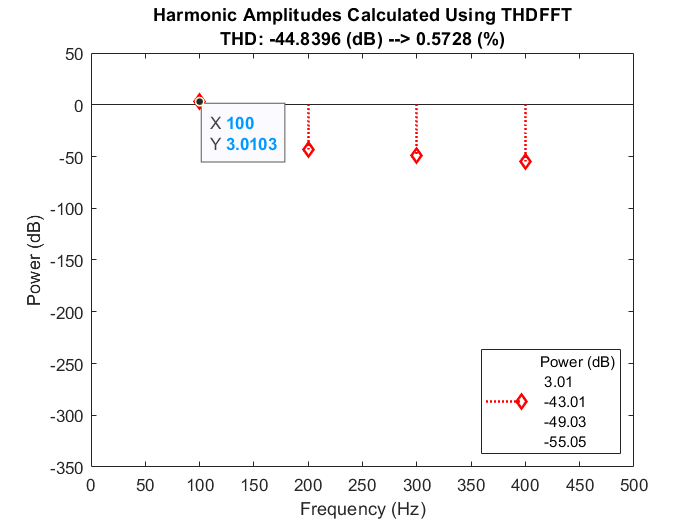


figure

st = stem(harmfreq_THDFFT, powerdB_THDFFT, ':diamondr','LineWidth', 1.5);
ylim([-350 50]);
xlim([0 500]);
str_dbs = sprintf('Power (dB)\n %.2f\n %.2f\n %.2f\n %.2f',powerdB_THDFFT(1), ...
powerdB_THDFFT(2), powerdB_THDFFT(3), powerdB_THDFFT(4));
legend(str_dbs, 'Location','SouthEast')
datatip(st, st.XData, st.YData);
ylabel('Power (dB)');
xlabel('Frequency (Hz)')
str_title = sprintf('Harmonic Amplitudes Calculated Using THDFFT\nTHD: %.4f (dB) --> %.4f (%%)', THD_THDFFT, Percent_THDFFT);
title(str_title)

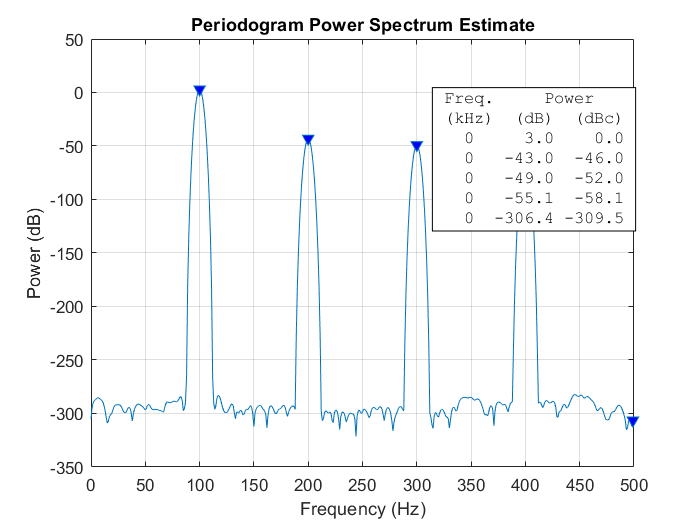

helperPlotPeriodogram(x, fs, 'power','annotate');

% Test THDFFT_V2 
inputs.data = x;
inputs.fs = fs;
inputs.Ff = Fn;
inputs.harmonic_order = oh;
outputs = THDFFT_V2(inputs);

harmonic_power = outputs.powerdB

harmonic_power =     3.0103  -43.0103  -49.0309  -55.0515


harmonic_frequency = outputs.harmfreq

harmonic_frequency =    100   200   300   400


harmonic_amplitude_rms = outputs.amplitude_rms

harmonic_amplitude_rms =     1.4142    0.0071    0.0035    0.0018


harmonic_amplitude_peak = harmonic_amplitude_rms .* sqrt(2)

harmonic_amplitude_peak =     2.0000    0.0100    0.0050    0.0025


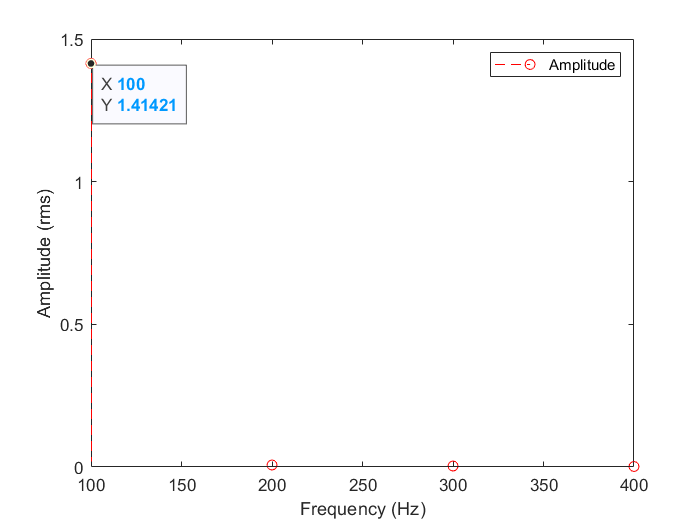


inputs_plot = outputs; 
plot_rms(inputs_plot, 'rms')

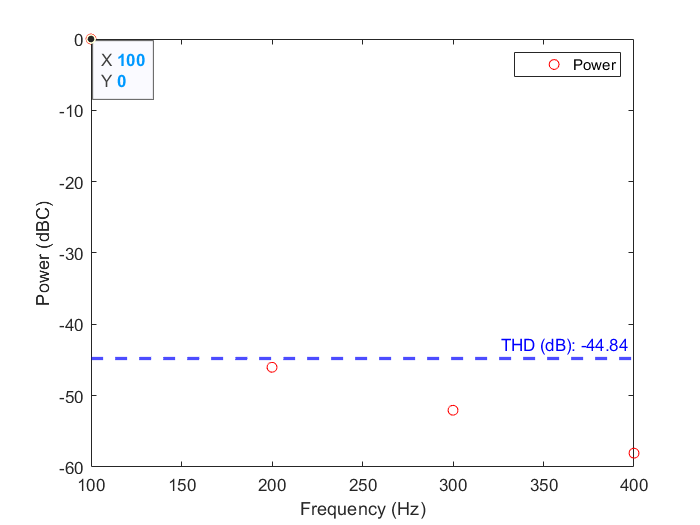

plot_rms(inputs_plot, 'dBc')

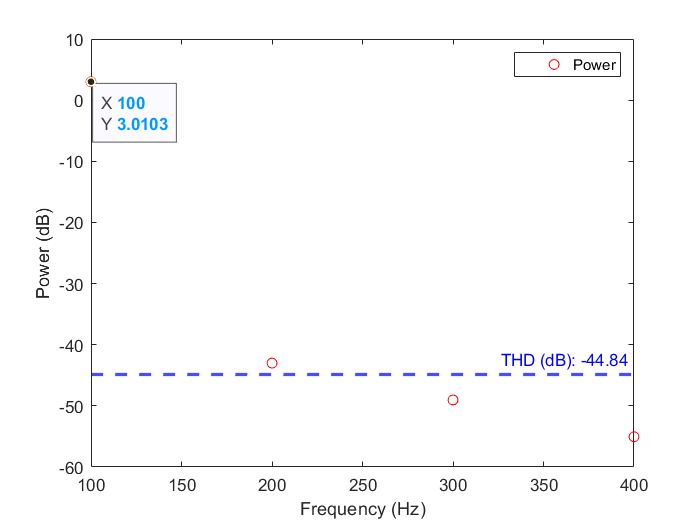

plot_rms(inputs_plot, 'dB')